## Benchmark of RAT Bayes Calculation

Start with a direct calculation of the posteriors for a simple problem. We use a simple reflectivity from D2O, and fit only two parameters - Roughness and background. 

The task is to calculate chi-squared on a 2D grid, with one axis representing roughness and the other background. For each pair of values, the likelihood is given by

 $P\propto \exp \left(-\frac{\chi^2 }{2}\right)$ . 

We calculate this on a grid, and this then gives the benchmark posterior distributions which can then be used to validate the two Bayes algorithms included in RAT.

1. **Calculation of 2D posterior.**

Start by setting up the problemDef and controlsDef input classes. We do this by converting from a RasCAL1 project.

[problem,controls] = r1ToProblemDef('defaultProject.mat')

problem =   problemDef with properties:

         experimentType: 'standard'
     experimentGeometry: 'air/substrate'
                nParams: 1
                 params: 4.8444
             paramNames: {'Substrate Roughness'}
            paramConstr: {[3 8]}
          paramFitYesNo: 1
           nBackgrounds: 1
            backgrounds: 3.0690e-06
        backgroundNames: {'Background 1'}
       backgroundConstr: {[5.0000e-08 7.0000e-06]}
     backgroundFitYesNo: 1
          nScalefactors: 1
           scalefactors: 0.1014
       scalefactorNames: {'Scalefactor 1'}
      scalefactorConstr: {[0.0100 0.3000]}
    scalefactorFitYesNo: 1
              nQzshifts: 1
               qzshifts: 0
           qzshiftNames: {'Qz Shifts 1'}
          qzshiftConstr: {[-0.0300 0.0300]}
        qzshiftFitYesNo: 0
          nbairFitYesNo: 0
                nNbsubs: 1
                 nbsubs: 6.3500e-06
             nbsubNames: {'D2O'}
   

controls =   controlsDef with properties:

            parallel: 'single'
           procedure: 'calculate'
    calcSldDuringFit: 'no'


Now we need to set up ranges for the parameters, and set up the calculation grid..

%Use a 30 x 30 grid.
%Make an array for the results...
gridSize = 30;
probArray = zeros(gridSize, gridSize);

%Make a vector of roughness values..
minRough = problem.paramConstr{1}(1);
maxRough = problem.paramConstr{1}(2);
roughVector = linspace(minRough, maxRough, gridSize);

%Also background...
minBack = problem.backgroundConstr{1}(1);
maxBack = problem.backgroundConstr{1}(2);
backsVector = linspace(minBack, maxBack, gridSize);

Now calculate the likelihood at all points on the grid

%Now for the calculation.
counter = 1;
totalGrid = gridSize^2;
controls.procedure = 'calculate';
tic;
for r = 1:gridSize
    for b = 1:gridSize
        thisRough = roughVector(r);
        thisBack =  backsVector(b);
        
        problem.params(1) = thisRough;
        problem.backgrounds(1) = thisBack;
        
        [outProblem,results] = RAT(problem,controls);
        thisChi = results.calculationResults.sum_chi;
        probArray(r,b) = exp(-thisChi/2);
        %percent = (counter/totalGrid)*100;
        %fprintf('Calculated %1.1f percent \n',percent);
        counter = counter + 1;
    end
end
toc;

Elapsed time is 1.261368 seconds.


We can now plot this to see the resulting 2D posterior....

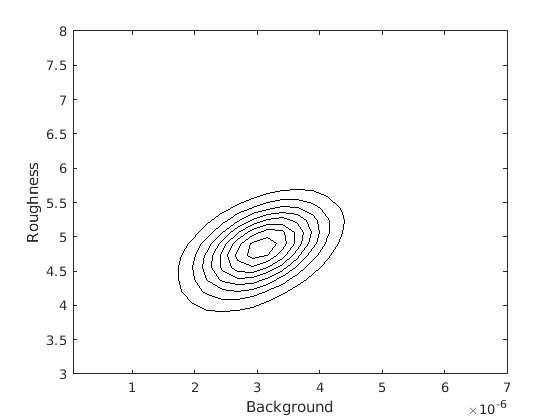

figure
contour(backsVector,roughVector,probArray,'k-');
hold on
xlabel('Background');
ylabel('Roughness')

We can now calculate the individual posterior distributions by margnalising along the other dimension. For roughness we sum over columns..

roughDist = sum(probArray,1);   % Sum over columns
backsDist = sum(probArray,2);   % Sum over rows

Normalise each distribution by simply dividing by the maximum value.

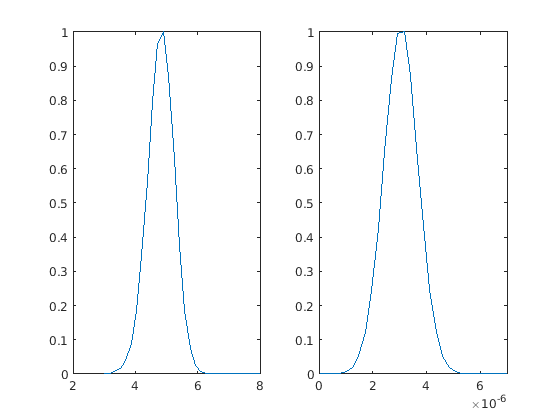

roughDist = roughDist ./ max(roughDist);
backsDist = backsDist ./ max(backsDist);

roughPosterior = [roughVector(:) backsDist(:)];
backsPosterior = [backsVector(:) roughDist(:)];

subplot(1,2,1);
plot(roughPosterior(:,1), roughPosterior(:,2));
subplot(1,2,2); 
plot(backsPosterior(:,1), backsPosterior(:,2));

### 2. Delayed Rejection Adaptive Metropolis.

Now run the analysis using DRAM, and compare the resulting posteriors to the calculated ones.

problem.scalefactorFitYesNo = 0;

controls.procedure = 'bayes'

controls =   controlsDef with properties:

            parallel: 'single'
           procedure: 'bayes'
    calcSldDuringFit: 'no'
              method: 'dram'
               nsimu: 1000
            adaptint: 1000
              burnin: 100
             repeats: 1


tic;
[outProb,results] = RAT(problem,controls)

Running loop 1 of 1
Sampling these parameters:
name   start [min,max] N(mu,s^2)
Substrate Roughness: 8 [3,8] N(0,Inf)
Background 1: 7e-06 [5e-08,7e-06] N(0,Inf)


outProb =   problemDef with properties:

         experimentType: 'standard'
     experimentGeometry: 'air/substrate'
                nParams: 1
                 params: 8
             paramNames: {'Substrate Roughness'}
            paramConstr: {[3 8]}
          paramFitYesNo: 1
           nBackgrounds: 1
            backgrounds: 7.0000e-06
        backgroundNames: {'Background 1'}
       backgroundConstr: {[5.0000e-08 7.0000e-06]}
     backgroundFitYesNo: 1
          nScalefactors: 1
           scalefactors: 0.1014
       scalefactorNames: {'Scalefactor 1'}
      scalefactorConstr: {[0.0100 0.3000]}
    scalefactorFitYesNo: 0
              nQzshifts: 1
               qzshifts: 0
           qzshiftNames: {'Qz Shifts 1'}
          qzshiftConstr: {[-0.0300 0.0300]}
        qzshiftFitYesNo: 0
          nbairFitYesNo: 0
                nNbsubs: 1
                 nbsubs: 6.3500e-06
             nbsubNames: {'D2O'}
        

results = struct with fields:
         res: [1×1 struct]
       chain: [5000×2 double]
     s2chain: []
     sschain: [5000×1 double]
    bestPars: [4.8483 3.0724e-06]


toc

Elapsed time is 7.208173 seconds.


We can get the posteriors from results.chain...

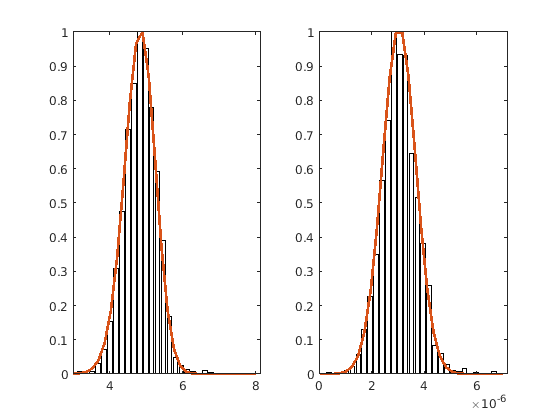

roughPostDram = results.chain(:,1);
backPostDram = results.chain(:,2);

[roughCounts,roughBins] = hist(roughPostDram,30);
roughCounts = roughCounts ./ max(roughCounts);

[backCounts,backBins] = hist(backPostDram,30);
backCounts = backCounts ./ max(backCounts);

subplot(1,2,1); bar(roughBins,roughCounts,'w');
hold on; plot(roughPosterior(:,1), roughPosterior(:,2), 'LineWidth', 2.0)
subplot(1,2,2); bar(backBins,backCounts,'w');
hold on; plot(backsPosterior(:,1), backsPosterior(:,2), 'LineWidth',2.0);

## 3. Nested Sampling

Nested sampling is primarily for model selection, but can be used to obtain the posteriors also. We do the same comparison as for DRAM.

In order to switch to NS, we just need to change the relevant flag in controlsDef...

controls.procedure = 'NS';
controls.Nlive = 200

controls =   controlsDef with properties:

            parallel: 'single'
           procedure: 'NS'
    calcSldDuringFit: 'no'
               Nlive: 200
               Nmcmc: 0
           propScale: 0.1000
         nsTolerance: 1


.. and run RAT..

tic;
[outNS,results] = RAT(problem,controls)

outNS =   problemDef with properties:

         experimentType: 'standard'
     experimentGeometry: 'air/substrate'
                nParams: 1
                 params: 8
             paramNames: {'Substrate Roughness'}
            paramConstr: {[3 8]}
          paramFitYesNo: 1
           nBackgrounds: 1
            backgrounds: 7.0000e-06
        backgroundNames: {'Background 1'}
       backgroundConstr: {[5.0000e-08 7.0000e-06]}
     backgroundFitYesNo: 1
          nScalefactors: 1
           scalefactors: 0.1014
       scalefactorNames: {'Scalefactor 1'}
      scalefactorConstr: {[0.0100 0.3000]}
    scalefactorFitYesNo: 0
              nQzshifts: 1
               qzshifts: 0
           qzshiftNames: {'Qz Shifts 1'}
          qzshiftConstr: {[-0.0300 0.0300]}
        qzshiftFitYesNo: 0
          nbairFitYesNo: 0
                nNbsubs: 1
                 nbsubs: 6.3500e-06
             nbsubNames: {'D2O'}
          

results = struct with fields:
            logX: -4.9176
    nest_samples: [887×3 double]
    post_samples: [280×4 double]
        fitNames: {2×1 cell}


toc

Elapsed time is 18.254502 seconds.


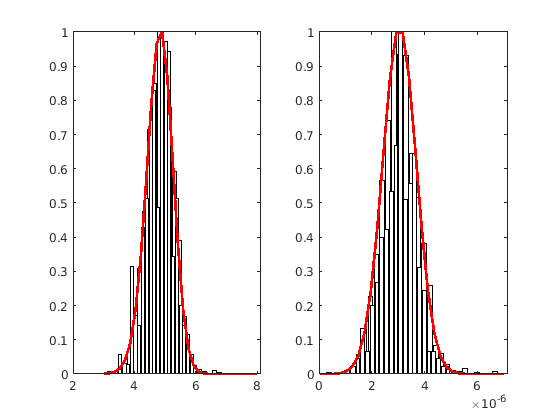

posteriors = results.post_samples;
roughPostNS = posteriors(:,1);
backPostNS = posteriors(:,2);

[roughCountsNS,roughBinsNS] = hist(roughPostNS,20);
roughCountsNS = roughCountsNS ./ max(roughCountsNS);

[backCountsNS,backBinsNS] = hist(backPostNS,20);
backCountsNS = backCountsNS ./ max(backCountsNS);

subplot(1,2,1); bar(roughBinsNS,roughCountsNS,'w');
hold on; plot(roughPosterior(:,1), roughPosterior(:,2),'r-', 'LineWidth', 2.0)
subplot(1,2,2); bar(backBinsNS,backCountsNS,'w');
hold on; plot(backsPosterior(:,1), backsPosterior(:,2),'r-', 'LineWidth',2.0);

## 3. Overall Comparison

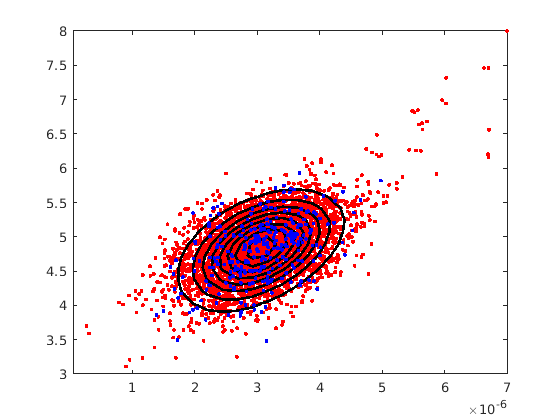

figure

hold on; box on

plot(backPostDram,roughPostDram,'r.')
contour(backsVector,roughVector,probArray,'k-','LineWidth',2);
plot(backPostNS,roughPostNS,'b.')